# Run Hergarten's minvoellmy model

## Prepare model

%% Load data
DEM = GRIDobj("data\grindelwald.txt");

%% Create detached volume
% X and Y coordinates of enclosing polygon
pos = [...
    6.4348    1.5869
    6.4360    1.5879
    6.4370    1.5885
    6.4387    1.5891
    6.4395    1.5897
    6.4392    1.5912
    6.4371    1.5933
    6.4359    1.5928
    6.4342    1.5908
    6.4319    1.5891] * 1e5;

MS = struct('Geometry','Polygon',...
    'X',pos(:,1),'Y',pos(:,2));

LS = polygon2GRIDobj(DEM,MS,'waitbar',false);

## Run minvoellmy

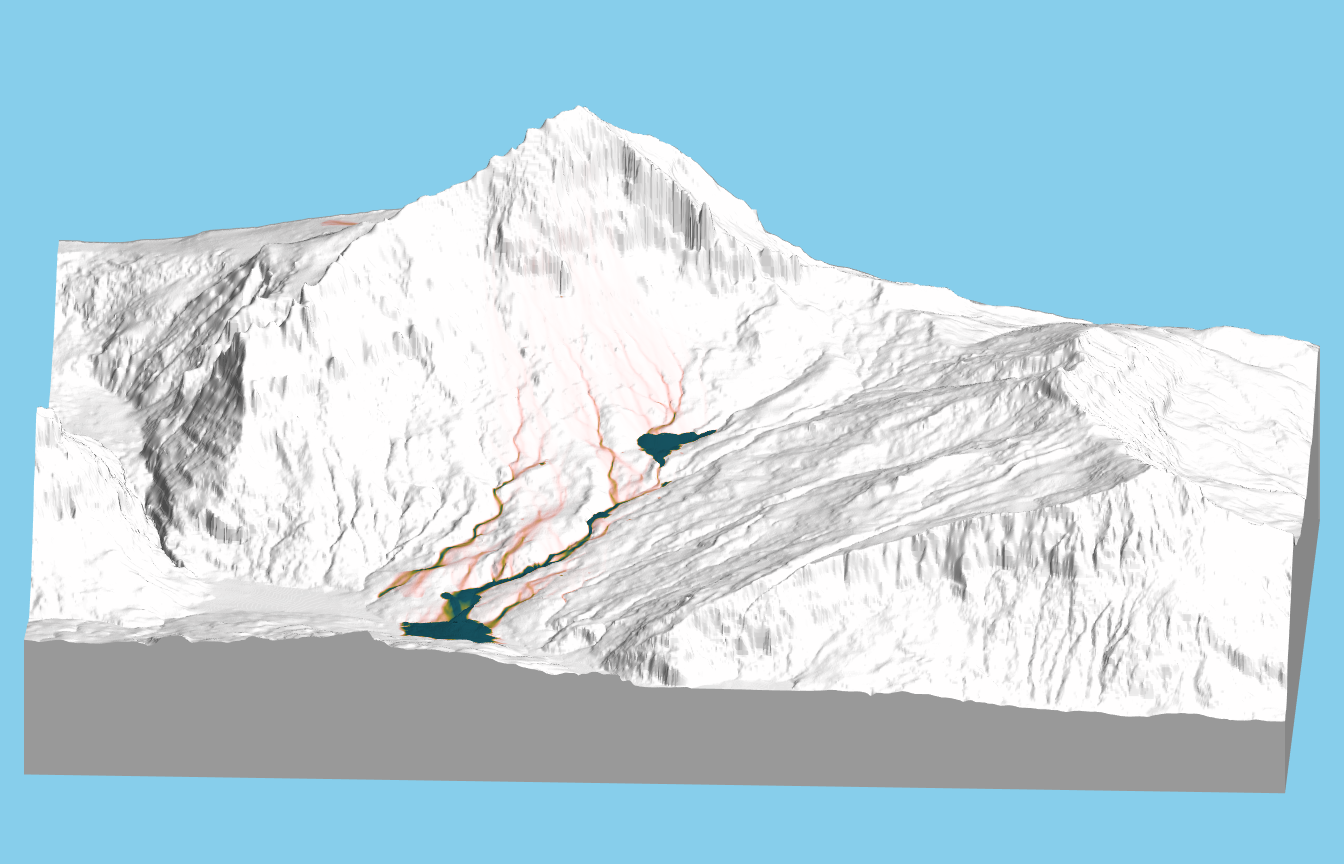

% Detached landslide depth [m]
H  = LS* 52;

[H2,T] = ttminvoellmy(DEM,H,"video",false,'maxtime',500,'camzoom',1.5,...
    'camorbit',[220 -10],'controls',false,'clim',[0 5], 'plotfreq', 2);